# Replicating Frässle et al. (2021) simulations

Why are my RMSE values so different than what is produced in Frässle et al. 

Can I replicate one of the networks used in their simulations to see if I can get RMSE's closer to the values they report in Frässle et al. (2021)?

E.g. model 4: four node network with 3 connectivity parameters (25% sparsity)

stim_options = get_default_stim_options();
nr = 4;

model4 = zeros(nr, nr);
model4(2, 1) = 1;
model4(3, 2) = 1;
model4(4, 3) = 1;

stim_options.n = nr;
stim_options.T = 300;
stim_options.A = ones(nr, nr);
stim_options.C = zeros(nr, nr);
stim_options.a = ones(nr, nr);
stim_options.c = zeros(nr);

num_sims = 20;
type = 'r';
output_sparse =  cell(1, num_sims);
output_ridge =  cell(1, num_sims);

Confirm you have the same SNR and TR settings

stim_options.SNR

ans = 3

stim_options.TR

ans = 2

Simulate 20 subjects by

- change true connectivity matrix in `stim_options`

- generate timeseries

- remove input used for the AR(1) process

- invert model using pruning

- replace DCM.a to specify which parameters to estimate

- invert model without pruning (as done in Frässle et al. (2021), HBM)

for i=1:num_sims
    
    warn_counter = 0;
    maxIter = 10;
    origState = warning;
    
    %when sampling random connectivity matrices sometimes activity
    %propogation ends up in singular matrices and fails. To avoid this I
    %added a while loop to resample a connectivity matrix and generate
    %timeseries
    while warn_counter<maxIter
        
        if warn_counter == 0
            fprintf("First try.\n");
        end
        
        % Sample connectivity parameters and make sure they are >0.05
        too_small = 1;
        while too_small
            
            %distribution for connectivity parameters comes from spm_dcm_fmri_priors.m
            A     =  model4 > 0;
            A     =  A - diag(diag(A));
            prior_means = A/(64*nr) - eye(nr,nr)/2;
            prior_sds = sqrt(A*8/nr + eye(nr,nr)/(8*nr));
            
            sampled_as = zeros(stim_options.n);
            for cur_row = 1:stim_options.n
                for cur_col = 1:stim_options.n
                    sampled_as(cur_row, cur_col) = normrnd(prior_means(cur_row, cur_col), prior_sds(cur_row, cur_col));
                end
            end
            
            %make sure only specified connections exist
            stim_options.Tp.A = sampled_as.*model4;
            
            %check and print value of too_small
            too_small = sum(sum(abs(stim_options.Tp.A)>0 & abs(stim_options.Tp.A)<0.05))
        end
       
       
        % Sample hemodynamic parameters from priors specified in
        % spm_dcm_fmri_priors.m
        stim_options.transit = normrnd(0,1/256,[stim_options.n,1]);
        stim_options.decay = normrnd(0,1/256);
        stim_options.epsilon = normrnd(0,1/256);
        
        warning('off');
        [DCM, options] = make_DEM_demo_induced_fmri(stim_options);
        [warnMsg, warnId] = lastwarn;
        
        %if there is a warning then increase and print the counter and try again
        if ~isempty(warnMsg)
            warn_counter = warn_counter + 1
        %if no warning push counter to quit the while loop
        else
            warn_counter = maxIter + 1;
            fprintf("No warnings.\n");
        end
        
        % Clear last warning message
        warning(''); 
    end
    warning(origState);

    %Remove input used for endogenous states
    if isfield(DCM, "U")
        DCM = rmfield(DCM,'U');
    end
    
    %Run sparse rDCM
    options.p0_all = 0.05:0.1:0.95;
    [output, options] = tapas_rdcm_estimate(DCM, type, options, 2);
    output_sparse{i} = output;
    
    %Run stabdard rDCM
    %Replace matrix to specify which parameters to estimate 
    DCM.a = logical(DCM.Tp.A);
    [output, options] = tapas_rdcm_estimate(DCM, type, options, 1);
    output_ridge{i} = output;
end

First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

warn_counter = 1

too_small = 0

warn_counter = 2

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 2

too_small = 0

warn_counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

warn_counter = 1

too_small = 0

warn_counter = 2

too_small = 0

warn_counter = 3

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

warn_counter = 1

too_small = 0

warn_counter = 2

too_small = 0

warn_counter = 3

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

warn_counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 1

too_small = 0

warn_counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 1

too_small = 0

warn_counter = 1

too_small = 0

warn_counter = 2

too_small = 0

warn_counter = 3

too_small = 0

warn_counter = 4

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

warn_counter = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

warn_counter = 1

too_small = 0

warn_counter = 2

too_small = 0

warn_counter = 3

too_small = 0

warn_counter = 4

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

warn_counter = 1

too_small = 0

warn_counter = 2

too_small = 0

warn_counter = 3

too_small = 0

warn_counter = 4

too_small = 0

warn_counter = 5

too_small = 1

too_small = 1

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


First try.


too_small = 1

too_small = 0

warn_counter = 1

too_small = 0

warn_counter = 2

too_small = 0

warn_counter = 3

too_small = 0

No warnings.



Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 10/10
Finalize results



Regression dynamic causal modeling (rDCM) 

Run model inversion

Finalize results


What is the distribution of RMSE's for **sparse rDCM**?

rmses = zeros(length(output_sparse),2);

for i=1:length(output_sparse)
    true_a = reshape(output_sparse{i}.allParam.par_true(1:nr*nr),4, 4);
    est_a = reshape(output_sparse{i}.allParam.par_est(1:nr*nr),4, 4);
    rmses(i,1) = get_rmse(true_a, est_a);
    est_a = reshape(output_ridge{i}.allParam.par_est(1:nr*nr),4, 4);
    rmses(i,2) = get_rmse(true_a, est_a);
end

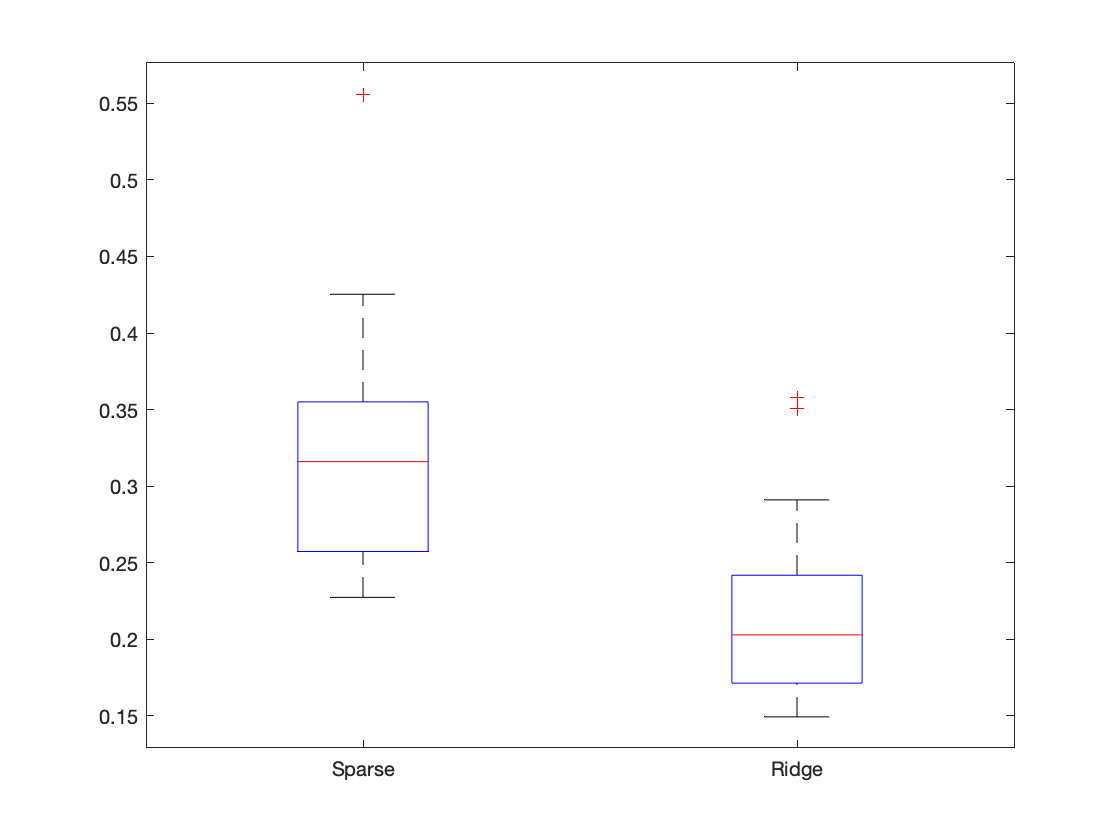

clf
boxplot(rmses);
xticklabels({'Sparse', 'Ridge'});